# DSZOB, cvičenie 6.

## **Zadanie:**

## **Úloha 1 **Filtrácia signálu gaussovským filtrom v časovej i frekvenčnej doméne

**a)**

- definujte fitracne jadro ako gaussovsku funkciu o dĺžke n (napr. 32 alebo 64)

- použite konvolúciu (funkciu **conv**) na filtrovanie signálu týmto gaussovským filtračným jadrom

**b)**

- vypočítajte spektrum filtračného jadra

- týmto spektrom filtračného jadra vynásobte (po prvkoch) spektrum vstupného signálu

- výstup dajte na vstup spätnej transformácii

Porovnavjte tieto dva spôsoby filtrácie !

Ako vstupný signál použite ľubovoľný signál zvuku alebo syntetizovaný zvuk so šumom.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

[y,Fs] = audioread('Fado1.wav');
x = 0:1/Fs:length(y)/Fs;
x = x(1:882000);

kernell = gausswin(64);
kernell = kernell ./ sum(kernell);  
y_window = y(100001:103072);
x_window = x(100001:103072);
convolved = conv(y_window, kernell, 'same');

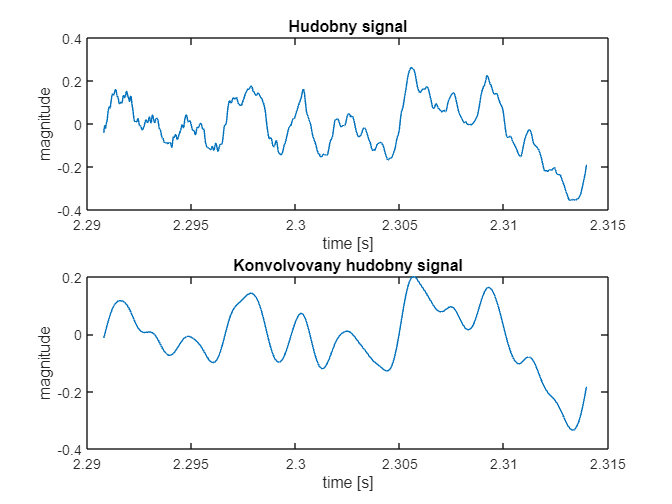

figure();
subplot(2,1,1);
plot(x_window(1025:2048), y_window(1025:2048))
title('Hudobny signal')
xlabel('time [s]')
ylabel('magnitude')
subplot(2,1,2);
plot(x_window(1025:2048), convolved(1025:2048))
title('Konvolvovany hudobny signal')
xlabel('time [s]')
ylabel('magnitude')

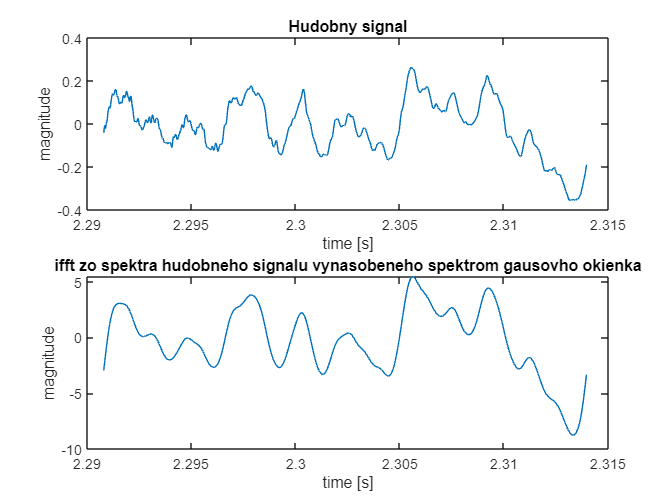

figure();
subplot(2,1,1);
plot(x_window(1025:2048), y_window(1025:2048))
title('Hudobny signal')
xlabel('time [s]')
ylabel('magnitude')
subplot(2,1,2);
result = fft(y_window(1025:2048)) .* abs(fft(gausswin(1024, 50)));
plot(x_window(1025:2048), ifft(result))
title('ifft zo spektra hudobneho signalu vynasobeneho spektrom gausovho okienka')
xlabel('time [s]')
ylabel('magnitude')

Výsledné signály boli vytvorené z toho istého okienka pôvodného signálu. To že po dvoch rôznych transformáciách je výsledok rovnaký (aspoň približne) sa dá vysvetliť konvolučným teorémom, ktorý nám vraví, že konvolúcia nejakým jadrom v časovej rovine je ekvivalentná s vynásobením spektrom jadra v spektrálnej rovine.

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

a) LP filter

- Filtrujte signál v spektrálnej oblasti za pomoci LP filtra (celý signál cez okienka)

- Použite rôzne hraničné hodnoty frekvencie

- Vizualizujte spektrogramom. Frekvenčná osa má byť preškálovaná na frekvencie v Hz!

b) HP filter

- Filtrujte signál v spektrálnej oblasti za pomoci HP filtra (celý signál cez okienka)

- Použite rôzne hraničné hodnoty frekvencie (cut-off freqency)

- Vizualizujte spektrogramom. Frekvenčná osa má byť preškálovaná na frekvencie v Hz!

Ako vstupné dáta použite:

- zvukový signál ladičky

- zvukový signál hudby

- zvukový signál reči

Vyhodnoťte zmenu kvality vypočutého filtrovaného zvuku pre rôzne typy  vstupného signálu a rôzne filtre. Nájdite hraničné  frekvencie pre LP a  HP, pri ktorej je reč na nahrávke ešte zrozumiteľná. Nezabudnite na to,  že pri filtrácií volíte hraničnú frekvenciu, nie hraničný spektrálny koeficient. Je teda nutné previesť indexy spektrálnych koeficientov na  frekvenciu.

## 2.1. Ladička:

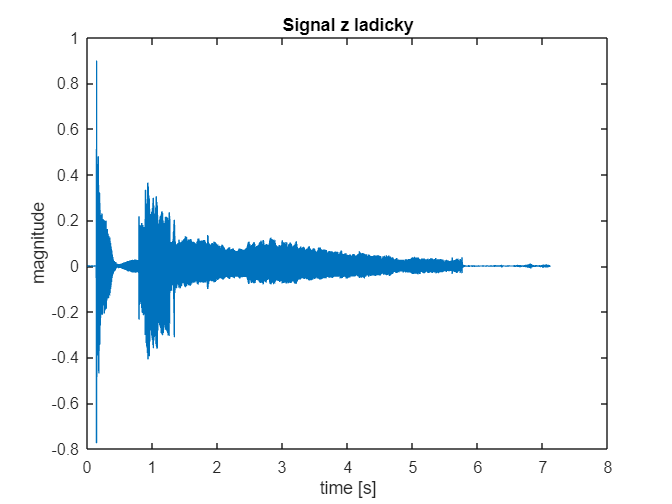

[y_fork,fs_fork] = audioread('a.m4a');
x_fork = 0:1/fs_fork:length(y_fork)/fs_fork;
x_fork = x_fork(1:313344);
figure();
plot(x_fork,y_fork)
title("Signal z ladicky")
xlabel("time [s]")
ylabel("magnitude")

## 2.1.1. Spektrum signálu ladičky:

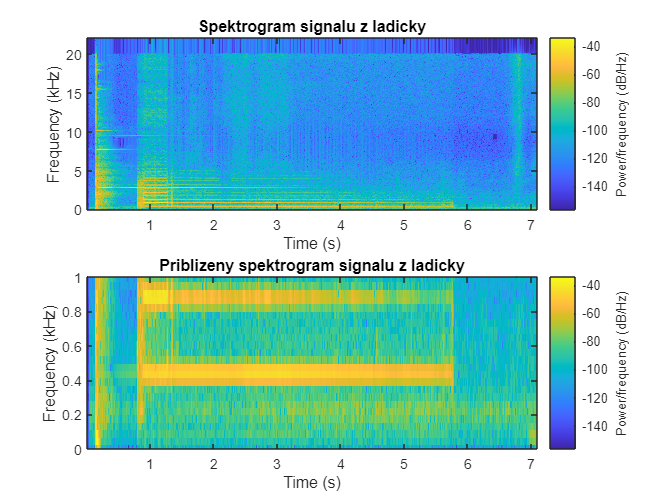

figure();
subplot(2,1,1);
spectrogram(y_fork,hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram signalu z ladicky")
subplot(2,1,2);
spectrogram(y_fork,hamming(1024), 512, 1024, 44100, 'yaxis')
title("Priblizeny spektrogram signalu z ladicky")
ylim([0, 1])

Ladička produkuje frekvenciu 440 Hz, takže v tomto prípade sa môžeme ďalej užšie zamerať na okolie tejto frekvencie.

## 2.1.2. Filtrácia signálu z ladičky:

Pri filtrácii takéhoto jednoduchého signálu vieme, že zaujímavá je pre nás len táto frekvencia a teda pomocou HP a LP filtrov spolu (spolu tvoria band pass) sa budem postupne približovať bližšie a bližšie k tejto cieľovej frekvencii.

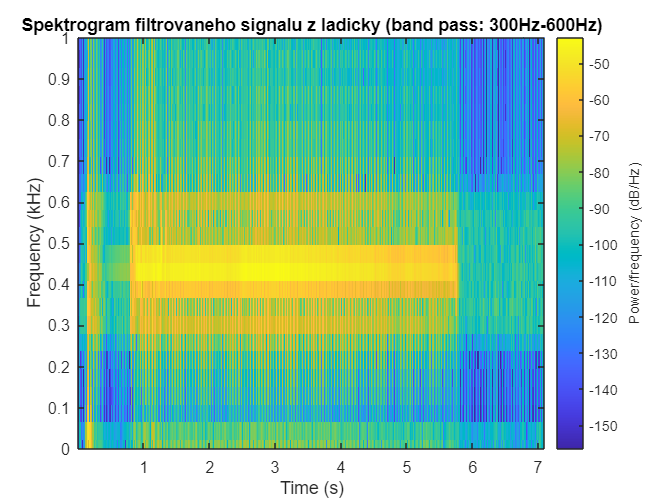

figure();
filtered = custom_filter(y_fork, 1024, 600, 44100, 'LP');
filtered = custom_filter(filtered, 1024, 300, 44100, 'HP');
spectrogram(filtered, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho signalu z ladicky (band pass: 300Hz-600Hz)")
ylim([0, 1])

sound(filtered, fs_fork)

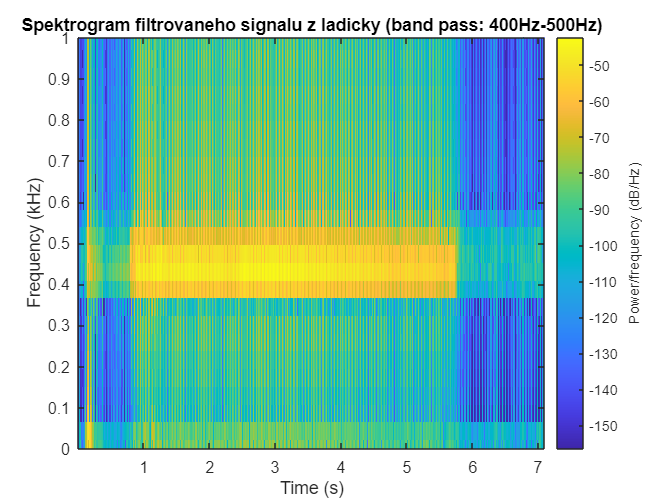

figure();
filtered = custom_filter(y_fork, 1024, 500, 44100, 'LP');
filtered = custom_filter(filtered, 1024, 400, 44100, 'HP');
spectrogram(filtered, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho signalu z ladicky (band pass: 400Hz-500Hz)")
ylim([0, 1])

sound(filtered, fs_fork)

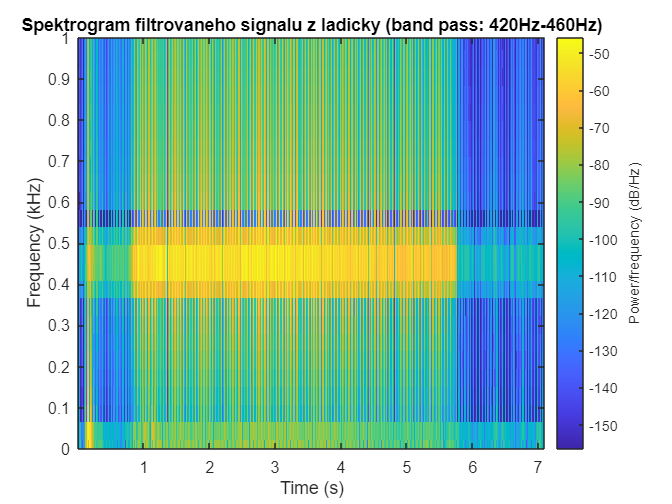

figure();
filtered = custom_filter(y_fork, 1024, 460, 44100, 'LP');
filtered = custom_filter(filtered, 1024, 420, 44100, 'HP');
spectrogram(filtered, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho signalu z ladicky (band pass: 420Hz-460Hz)")
ylim([0, 1])

sound(filtered, fs_fork)

Postupné zužovanie filtrov znižovalo kvalitu zvuku, ale kým ponecháme v signále očakávanú frekvenciu ladičky, čiže 440 Hz, hlavná informácia ostane zachovaná.

## 2.2. Hudba:

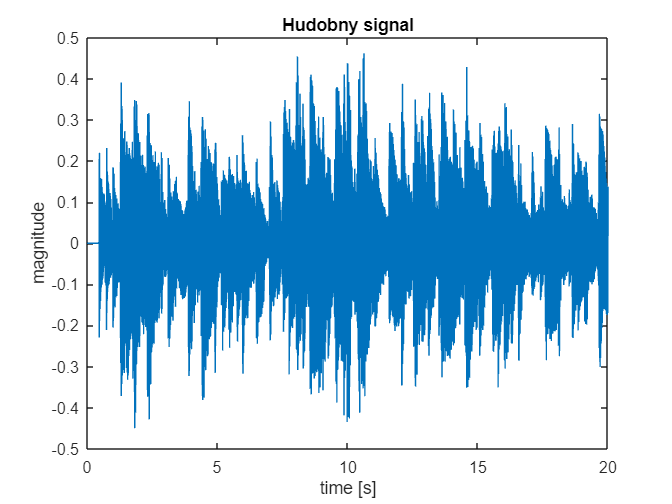

[y_fado,fs_fado] = audioread('Fado1.wav');
x_fado = 0:1/fs_fado:length(y_fado)/fs_fado;
x_fado = x_fado(1:882000);
figure();
plot(x_fado,y_fado)
title("Hudobny signal")
xlabel("time [s]")
ylabel("magnitude")

## 2.2.1. Spektrum hudobného signálu: 

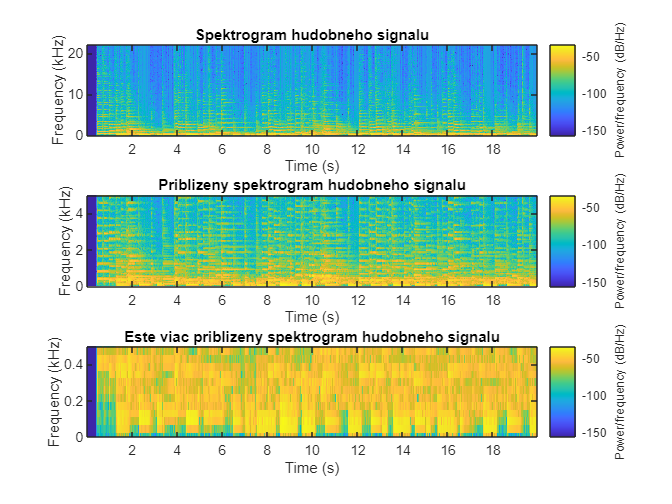

figure();
subplot(3,1,1);
spectrogram(y_fado, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram hudobneho signalu")
subplot(3,1,2);
spectrogram(y_fado, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Priblizeny spektrogram hudobneho signalu")
ylim([0, 5])
subplot(3,1,3);
spectrogram(y_fado, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Este viac priblizeny spektrogram hudobneho signalu")
ylim([0, 0.5])

Narozdiel od signálu z ladičky v hudbe máme spektrum pestrejšie a teda musíme brať do úvahy väčšiu časť z neho a navrhnúť správne hranice filtrov je väčší problém.

## 2.2.2. Filtrácia hudobného signálu:

Ako vidieť z tretieho spektrogramu, nízke frekvencie sú pomerne výrazné a teda ak by sme chceli použiť high pass filter, môže byť nanajvýš veľmi jemný.

HP_25 = custom_filter(y_fado, 1024, 25, 44100, 'HP');
HP_50 = custom_filter(y_fado, 1024, 50, 44100, 'HP');

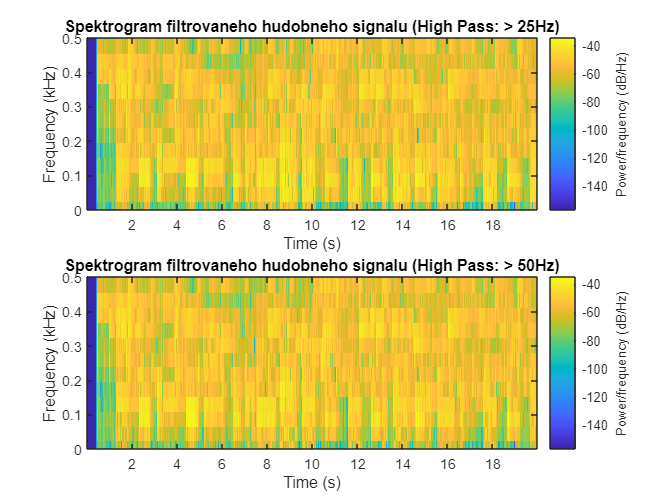

figure();
subplot(2,1,1);
spectrogram(HP_25, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (High Pass: > 25Hz)")
ylim([0, 0.5])
subplot(2,1,2);
spectrogram(HP_50, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (High Pass: > 50Hz)")

ylim([0, 0.5])

sound(HP_25, fs_fado)

sound(HP_50, fs_fado)

Aj takéto relatívne jemné HP filtre v nižších frekvenciách spôsobili výpadky a praskanie. Ani jeden z nich teda nie je úplne vhodné použiť.

LP_15k = custom_filter(y_fado, 1024, 15000, 44100, 'LP');
LP_10k = custom_filter(y_fado, 1024, 10000, 44100, 'LP');
LP_05k = custom_filter(y_fado, 1024,  5000, 44100, 'LP');
LP_02k = custom_filter(y_fado, 1024,  2000, 44100, 'LP');

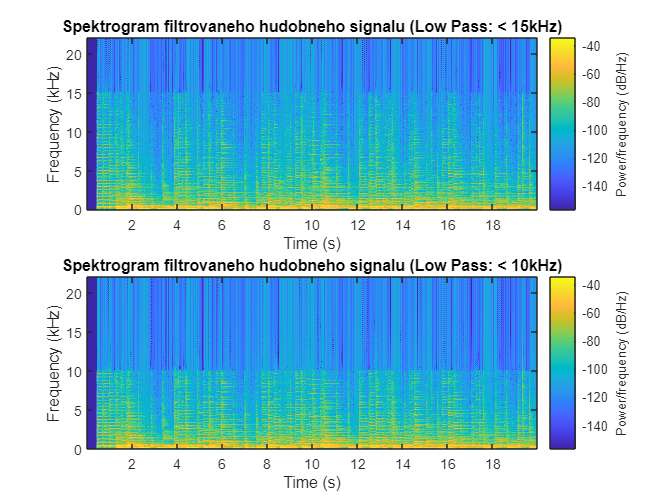

figure();
subplot(2,1,1);
spectrogram(LP_15k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (Low Pass: < 15kHz)")
subplot(2,1,2);
spectrogram(LP_10k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (Low Pass: < 10kHz)")

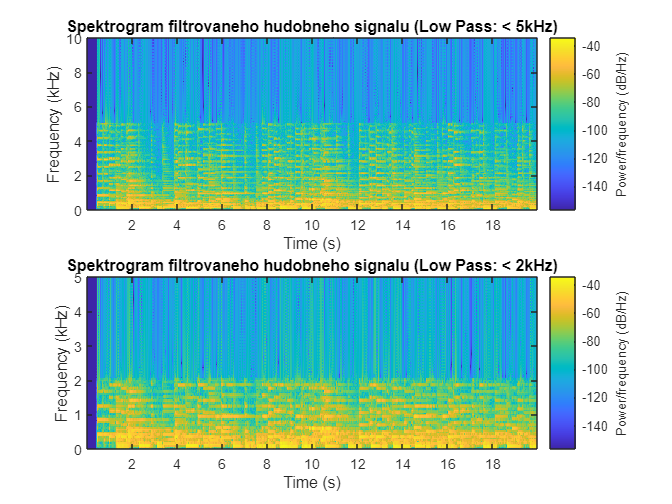

figure();
subplot(2,1,1);
spectrogram(LP_05k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (Low Pass: < 5kHz)")
ylim([0, 10])
subplot(2,1,2);
spectrogram(LP_02k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (Low Pass: < 2kHz)")
ylim([0, 5])

sound(LP_15k, fs_fado)

sound(LP_10k, fs_fado)

sound(LP_05k, fs_fado)

sound(LP_02k, fs_fado)

Odfiltrovaním len frekvencií vyšších ako 15 alebo 10 kHz sme na počutie nestratili kvalitu zvuku a teda nad touto hranicou sú tie frekvencie "nepotrebné". Od tých 5 kHz sme sa však už dotýkali dôležitých frekvencií, bez ktorých je zvuk už deformovaný.

Takže vo výsledku je asi najlepšie nepoužiť žiadny HP filter a použiť len LP filter sa cufoff frekvenciou cca 10kHz.

## 2.3. Reč:

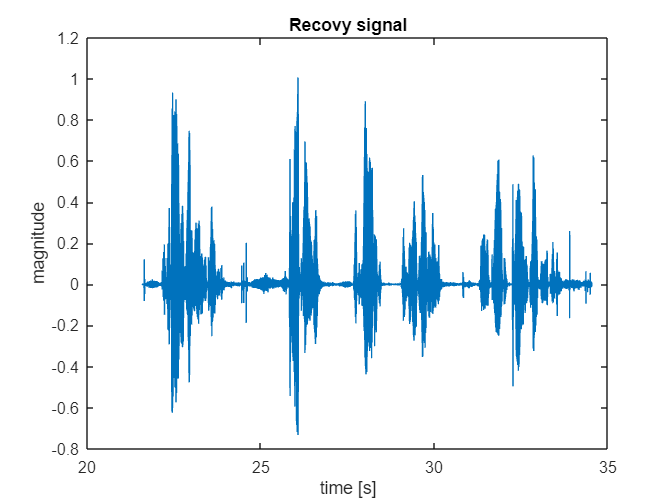

[y_speech,fs_speech] = audioread('speech.oga');
x_speech = 0:1/fs_speech:length(y_speech)/fs_speech;
y_speech = y_speech(:,1);
y_speech = y_speech(952001:1523000);
x_speech = x_speech(952001:1523000);
sound(y_speech, fs_speech)
figure();
plot(x_speech,y_speech)
title('Recovy signal')
xlabel('time [s]')
ylabel('magnitude')

## 2.3.1. Spektrum rečového signálu:

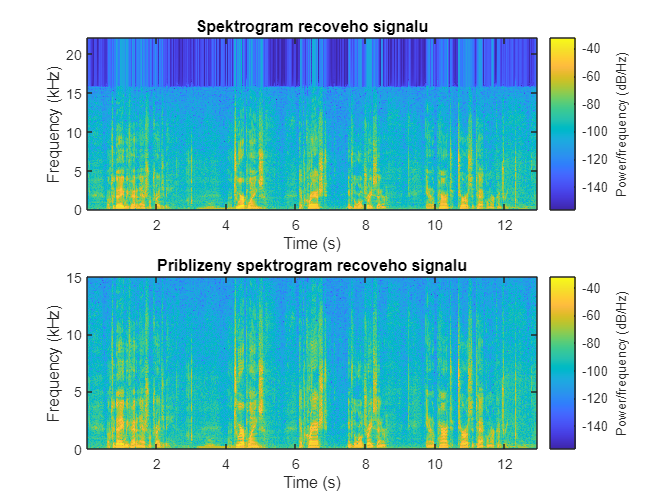

figure();
subplot(2,1,1);
spectrogram(y_speech, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram recoveho signalu")
subplot(2,1,2);
spectrogram(y_speech, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Priblizeny spektrogram recoveho signalu")
ylim([0, 15])

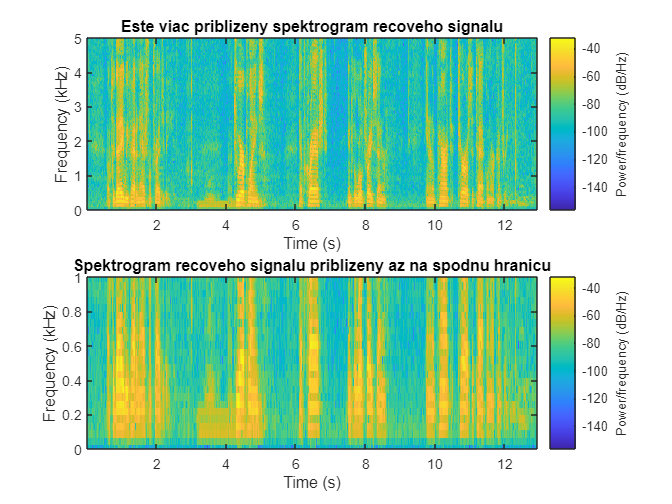

figure();
subplot(2,1,1);
spectrogram(y_speech, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Este viac priblizeny spektrogram recoveho signalu")
ylim([0, 5])
subplot(2,1,2);
spectrogram(y_speech, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram recoveho signalu priblizeny az na spodnu hranicu")
ylim([0, 1])

Rovnako ako hudba aj reč má pestrejšie, nie jednoduché, spektrum. Ale zo spektrogramu vidieť, že frekvencie nad cca 15 kHz alebo pod 0,1 kHz prakticky nie sú zastúpene a teda to je dobrý podklad pre filtráciu.

## 2.3.2. Filtrácia rečového signálu:

HP_50 = custom_filter(y_speech, 1024, 50, 44100, 'HP');
HP_100 = custom_filter(y_speech, 1024, 100, 44100, 'HP');

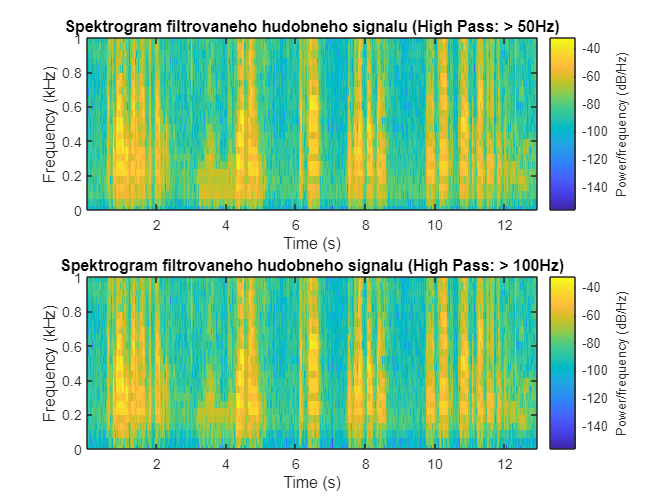

figure();
subplot(2,1,1);
spectrogram(HP_50, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (High Pass: > 50Hz)")
ylim([0, 1])
subplot(2,1,2);
spectrogram(HP_100, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (High Pass: > 100Hz)")
ylim([0, 1])

sound(HP_50, fs_speech)

sound(HP_100, fs_speech)

Ani jeden z týchto filtrov ešte nezasiahol do  kvality reči samotnej. Nanajvýš zvukov v pozadí.

HP_200 = custom_filter(y_speech, 1024, 200, 44100, 'HP');
HP_400 = custom_filter(y_speech, 1024, 400, 44100, 'HP');

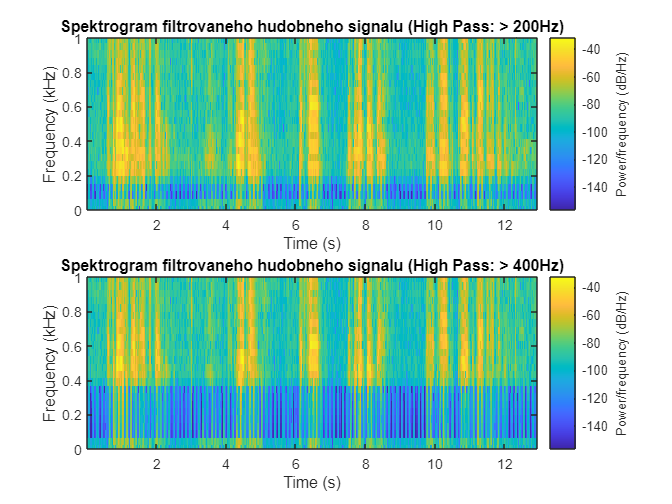

figure();
subplot(2,1,1);
spectrogram(HP_200, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (High Pass: > 200Hz)")
ylim([0, 1])
subplot(2,1,2);
spectrogram(HP_400, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho hudobneho signalu (High Pass: > 400Hz)")
ylim([0, 1])

sound(HP_200, fs_speech)

sound(HP_400, fs_speech)

Pri High Pass filtri 200 Hz je deformácia reči veľmi jemná, ale nad 400 Hz už je deformácia citeľná.

LP_15k = custom_filter(y_speech, 1024, 15000, 44100, 'LP');
LP_10k = custom_filter(y_speech, 1024, 10000, 44100, 'LP');
LP_05k = custom_filter(y_speech, 1024,  5000, 44100, 'LP');
LP_02k = custom_filter(y_speech, 1024,  2000, 44100, 'LP');

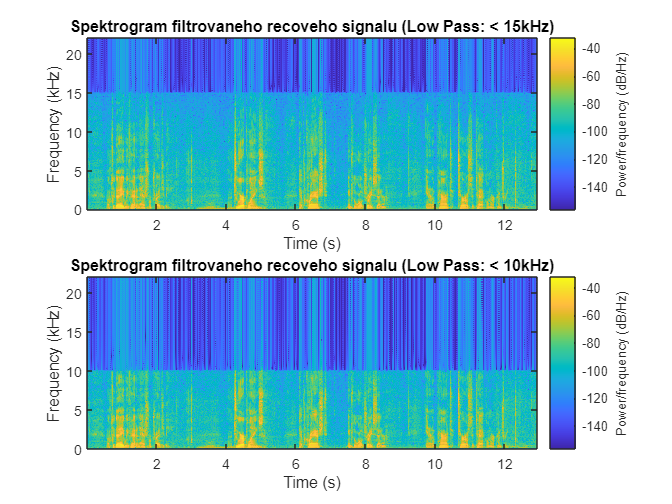

figure();
subplot(2,1,1);
spectrogram(LP_15k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho recoveho signalu (Low Pass: < 15kHz)")
subplot(2,1,2);
spectrogram(LP_10k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho recoveho signalu (Low Pass: < 10kHz)")

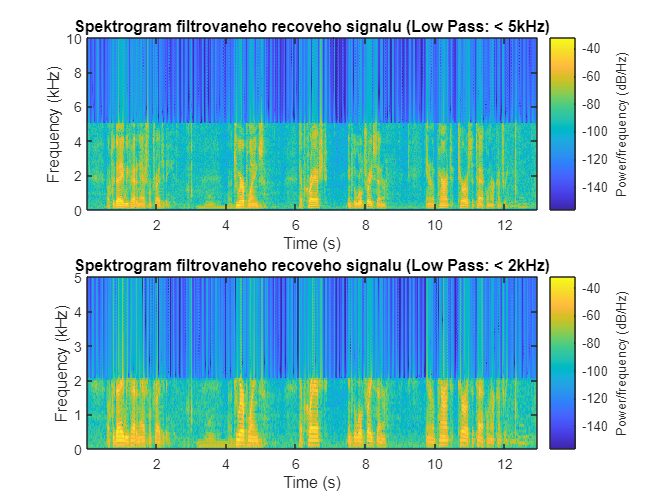

figure();
subplot(2,1,1);
spectrogram(LP_05k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho recoveho signalu (Low Pass: < 5kHz)")
ylim([0, 10])
subplot(2,1,2);
spectrogram(LP_02k, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho recoveho signalu (Low Pass: < 2kHz)")
ylim([0, 5])

sound(LP_15k, fs_speech)

sound(LP_10k, fs_speech)

sound(LP_05k, fs_speech)

sound(LP_02k, fs_speech)

Nad 15 kHz ani v pôvodnom signále nič nebolo, takže low pass pod 15 kHz je bez zmeny.

Pod 10 je reč stále veľmi zrozumiteľná a deformácia nie je citeľná.

Pod 5 a pod 2 kHz sú vety stále zrozumiteľné, ale reč je výrazne deformovaná a kvalita je nižšia.

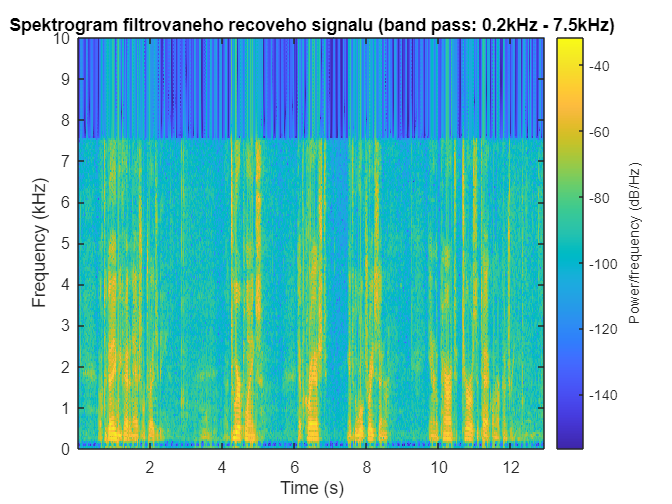

filtered = custom_filter(y_speech, 1024, 7500, 44100, 'LP');
filtered = custom_filter(filtered, 1024,  200, 44100, 'HP');
figure();
spectrogram(filtered, hamming(1024), 512, 1024, 44100, 'yaxis')
title("Spektrogram filtrovaneho recoveho signalu (band pass: 0.2kHz - 7.5kHz)")
ylim([0, 10])

sound(filtered, fs_speech)

Takto definovaný Band Pass filter sa mi javil ako najlepsi tradeoff medzi odfiltrovaním, čo najviac a zachovaním, čo najvyššiu kvalitu.

function transformed = custom_filter(y, win_size, cutoff, fs, kind)
    tmp_y = zeros(1, ceil(length(y)/win_size)*win_size);
    tmp_y(1:length(y)) = y;
    transformed = zeros(1, length(tmp_y));

    frequencies = 1:(fs/2)/win_size:(fs/2);
    cutoff_index = find(frequencies >= cutoff, 1);

    for index = 1:win_size:length(tmp_y)
        dct_1 = dct(tmp_y(index: index + win_size - 1));

        if strcmp(kind, 'HP')
            dct_1(2:cutoff_index) = 0;
        else
            dct_1(cutoff_index:win_size) = 0;
        end
        
        transformed(index: index + win_size - 1) = idct(dct_1);
    end

    transformed = transformed(1:length(y));
end